# Convert Between Image Sequences and Video

Convert between video files and sequences of image files using `VideoReader` and `VideoWriter`.

The sample file named `shuttle.avi` contains 121 frames. Convert the frames to image files using `VideoReader` and the `imwrite` function. Then, convert the image files to an AVI file using `VideoWriter`.

## Setup

Create a temporary working folder to store the image sequence.

workingDir = tempname;
mkdir(workingDir)
mkdir(workingDir,'images')

## Create VideoReader

Create a `VideoReader` to use for reading frames from the file.

shuttleVideo = VideoReader("C:\Users\USER\Downloads\video (1080p).mp4");

## Create the Image Sequence

Loop through the video, reading each frame into a width-by-height-by-3 array named `img`. Write out each image to a JPEG file with a name in the form `imgN.jpg`, where N is the frame number.

| img001.jpg|

| img002.jpg|

| ...|

| img121.jpg|

ii = 1;

while hasFrame(shuttleVideo)
   img = readFrame(shuttleVideo);
   filename = [sprintf('%03d',ii) '.jpg'];
   fullname = fullfile(workingDir,'images',filename);
   imwrite(img,fullname)    % Write out to a JPEG file (img1.jpg, img2.jpg, etc.)
   ii = ii+1;
end

## Find Image File Names

Find all the JPEG file names in the `images` folder. Convert the set of image names to a cell array.

imageNames = dir(fullfile(workingDir,'images','*.jpg'));
imageNames = {imageNames.name}';

## Create New Video with the Image Sequence

Construct a `VideoWriter` object, which creates a Motion-JPEG AVI file by default.

outputVideo = VideoWriter(fullfile(workingDir,'shuttle_out.avi'));
outputVideo.FrameRate = shuttleVideo.FrameRate;
open(outputVideo)

Loop through the image sequence, load each image, and then write it to the video.

for ii = 1:length(imageNames)
   img = imread(fullfile(workingDir,'images',imageNames{ii}));
   writeVideo(outputVideo,img)
end

Finalize the video file.

close(outputVideo)

## View the Final Video

Construct a reader object.

shuttleAvi = VideoReader(fullfile(workingDir,'shuttle_out.avi'));

Create a MATLAB® movie struct from the video frames.

ii = 1;
while hasFrame(shuttleAvi)
   mov(ii) = im2frame(readFrame(shuttleAvi));
   ii = ii+1;
end

Resize the current figure and axes based on the video's width and height, and view the first frame of the movie.

figure 
imshow(mov(1).cdata, 'Border', 'tight')

Play back the movie once at the video's frame rate.

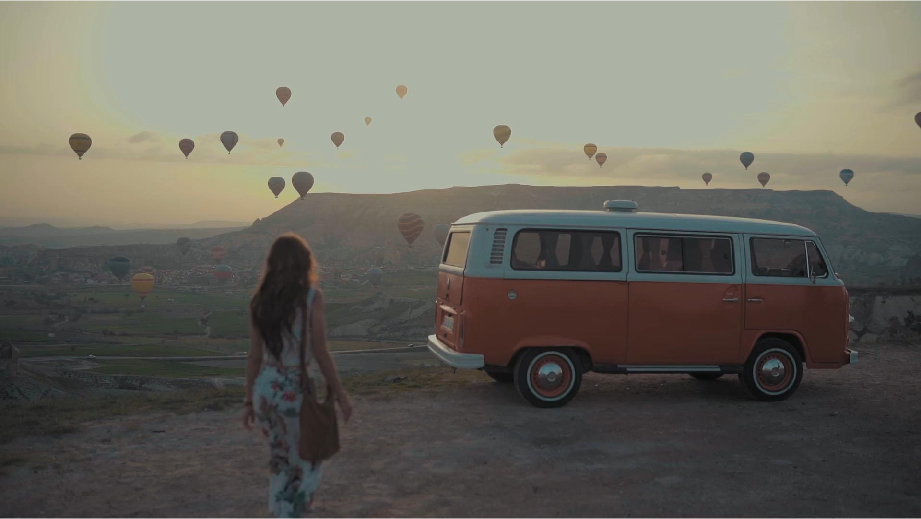

movie(mov,1,shuttleAvi.FrameRate)

## Credits

Video of the Space Shuttle courtesy of NASA.

*Copyright 2014 The MathWorks, Inc.*